%システム定義
A=[0 1;-2 3]

A =      0     1
    -2     3


b=[0;1]

b =      0
     1


x0=[1;1]

x0 =      1
     1


%安定性の確認
eig(A)

ans =      1
     2


%可制御性の確認
Uc=[b A*b]

Uc =      0     1
     1     3


det(Uc)

ans = -1

%極配置
clear i
syms f1 f2 real
syms s
%Afの特性多項式
Af=A-b*f;
T1=det(s*eye(2)-Af)

$$T1 = f_{1}-3\,s+f_{2}\,s+s^{2}+2$$

%望みの特性多項式
T2=expand((s - (0.1 + i)) * (s + (0.1 - i)))

$$T2 = s^{2}-2\,s\,\mathrm{i}-\frac{101}{100}$$


F=subs([f1 f2],solve(coeffs(T1,s)==coeffs(T2,s),[f1 f2]))

 
F =
 
Empty sym: 0-by-2
 


%閉ループ系の応答確認
%F=place(A,b,[-0.1+i,-0.1-i]);
F=[0.01-2+1 -0.01+3];
Af=A-b*F;
eig(Af)

ans =    0.0050 + 1.0050i
   0.0050 - 1.0050i


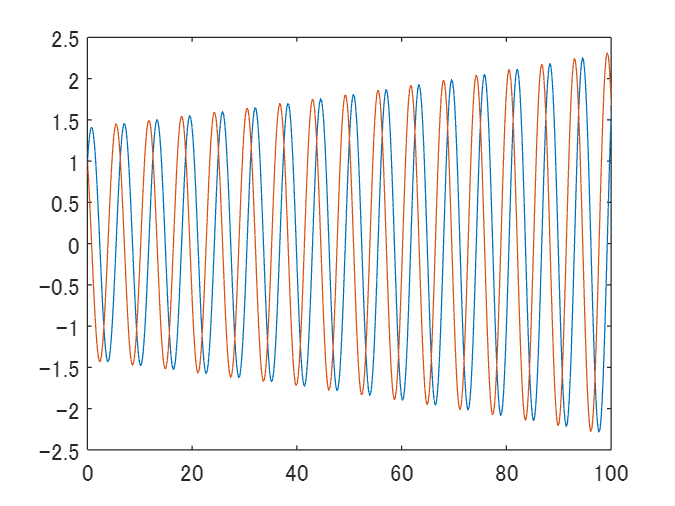


xlabel('t');
ylabel('x(t)');


[T,X]=ode45(@(t,x) Af*x,[0 100],x0);
plot(T,X)